clc
close all
clearvars

% Folder in which all test data folders are located
rcbench_folder = ['C:\Users\Tomaso\Desktop\Thesis\main\RC Testbench Data\RC Testbench Data' ];
 %'C:\Users\Tomaso\Desktop\Thesis\main\RC Testbench Data\RC Testbench Data'
 %'/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/RC Testbench Data/RC Testbench Data'

% List of folders of the specific tests
test_folder = {...'T-motor F80 Pro 1900 kv - GemFan 6030 4R(green) - 4S'
              ...'T-motor F80 Pro 1900 kv - Qprop 5x4x3 (pink) - 4S'
              ...'T-motor F80 Pro 1900 kv 7x4R (orange) - 4S'
              ...'T-motor MN3515 400 kv - APC 13x10EP - 6S - Pusher'
              ...'T-motor MN3515 400 kv - APC 14x8.5EP - 6S - Pusher'
              ...'T-motor MN3515 400 kv - APC 16x10EP - 6S - Pusher'
              ...'T-motor MN3510 360 kv - APC 11x5.5 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 12x6 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 12x12 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 11x5.5 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 12x6 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 12x12 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 13x10 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 13x10 EP - 6S - Pusher'
              ...'T-motor MN3510 360 kv - APC 14x8.5 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 16x10 EP - 6S'
              ...'T-motor MN3510 360 kv - MF1302R - 4S'
              ...'T-motor MN3510 360 kv - MF1302R - 4S - Pusher'
              'T-motor MN3510 360 kv - MF1302R - 6S'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - Pusher'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - pusher - esc settings'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - Pusher - ESC 48 khz'
              ...'T-motor MN3510 360 kv - MF1302R FW folding hub - 6S - Pusher'
              };

%% Get the data
for n = 1:length(test_folder)
    folder = fullfile(rcbench_folder, test_folder{n});
    data{n} = RCTestbench.getData(folder);
%     data{n} = data{n}.getFOM;
end

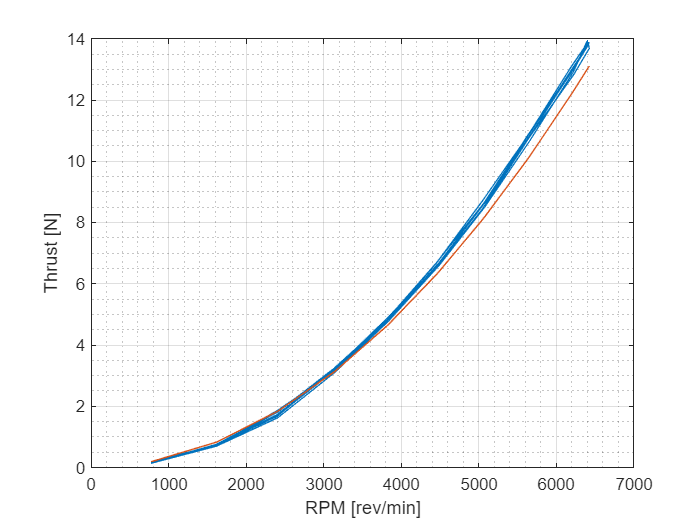

pwm = [data{1,1}.perf.test1.pwm;data{1,1}.perf.test2.pwm;data{1,1}.perf.test3.pwm];
T =  [data{1,1}.perf.test1.T;data{1,1}.perf.test2.T;data{1,1}.perf.test3.T];
Qm =  [data{1,1}.perf.test1.Qm;data{1,1}.perf.test2.Qm;data{1,1}.perf.test3.Qm];
rpm = [data{1,1}.perf.test1.RPM;data{1,1}.perf.test2.RPM;data{1,1}.perf.test3.RPM];


d = 339.8e-3;
pitch = 121.6;
r = d/2;
radius=r;
bp = 1/3*r; %1/3
rpm0 = min(rpm);
rpm2rads= 2*pi/60;
w0 = rpm0 * rpm2rads;
%Vt_q = linspace(0,30,5);
Vt_q =[0  5 10 16 19 23];
w = Vt_q./bp+w0;
rpm_min = w./rpm2rads;

[X,Y]=meshgrid(rpm_min,rpm);
query_mat=Y>X;
rcCL = T./(rpm.*rpm2rads).^2 .* (3/r^3);
rcCL_m = mean(rcCL);


figure(1)
clf
plot(rpm,T)
hold on
plot(rpm,r*(1/3*r^2*(rpm.*rpm2rads).^2).*rcCL_m)
grid on
grid minor
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')

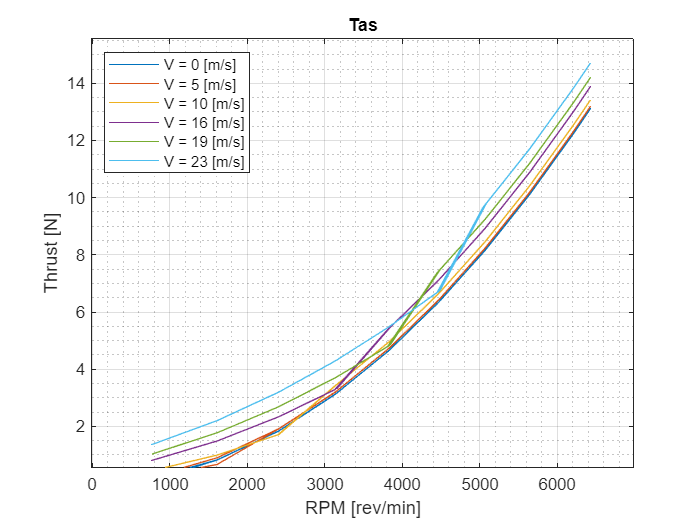


fun = @(x,rev,as,rcCl) 0.5*rcCL_m*(rev*x+as).^2+0.5*rcCL_m*max(0,(rev*x-as)).^2;
T_as_2 = zeros(size(rpm,1),size(Vt_q,2));
for k=1:size(rpm,1)
    for j=1:size(Vt_q,2)
        T_as_2(k,j)= integral(@(x) fun(x,rpm(k,1)*rpm2rads,Vt_q(1,j),rcCL_m),0,r);
    end
end


%T_as = (T + rcCL * r * Vt_q.^2).*query_mat+ 0.5*rcCL*r*(1/3*r^2*(rpm.*rpm2rads).^2+r*(rpm.*rpm2rads)*Vt_q+Vt_q.^2).*(1-query_mat);
T_as = rcCL_m * r *(1/3*r^2*(rpm.*rpm2rads).^2+Vt_q.^2).*query_mat+ 0.5*rcCL_m*r*(1/3*r^2*(rpm.*rpm2rads).^2+r*(rpm.*rpm2rads)*Vt_q+Vt_q.^2).*(1-query_mat);
T_as_3 = (T + rcCL_m * r * Vt_q.^2).*query_mat+T_as_2.*(1-query_mat);
rpm_q = linspace(rpm0,max(rpm),100);

figure(3)
clf
plot(rpm,T_as.')
legendStrings = "V = " + string(round(Vt_q))+" [m/s]";
legend(legendStrings,'Location','northwest')
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')
grid on
grid minor
title('Tas')

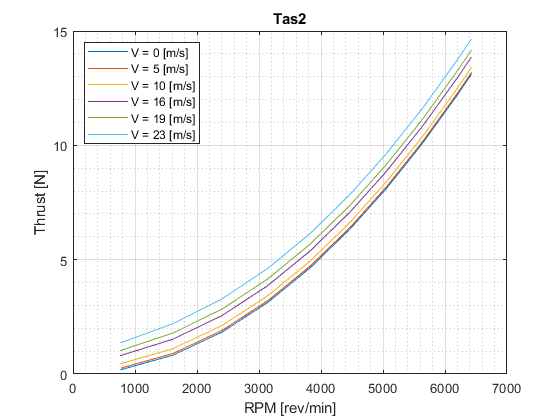


figure(4)
clf
plot(rpm,T_as_2.')
legendStrings = "V = " + string(round(Vt_q))+" [m/s]";
legend(legendStrings,'Location','northwest')
grid on
grid minor
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')
title('Tas2')

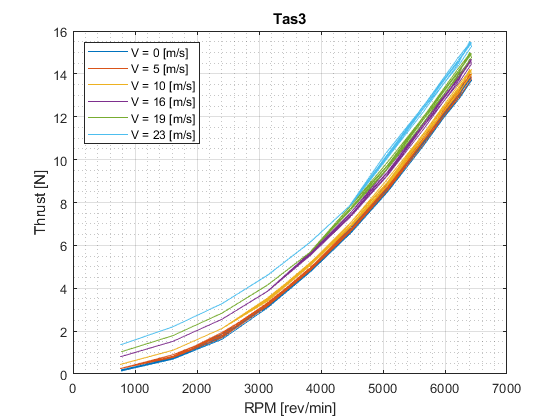


figure(5)
clf
plot(rpm,T_as_3.')
legendStrings = "V = " + string(round(Vt_q))+" [m/s]";
legend(legendStrings,'Location','northwest')
grid on
grid minor
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')
title('Tas3')

syms r rho Cl A B m w Vt c R C
c(A,B,r,R) = (A-B)/R*r+A;
dT(rho,Cl,w,Vt,A,B,r,R)= 0.5*rho*(w*r+Vt)^2*Cl*c+0.5*rho*(w*r-Vt)^2*Cl*c;%c(A,B,r);
T_fun =int(dT(rho,Cl,w,0,2.7,1.09,r,radius),r,[0 radius])

$$T\_fun = \frac{2555158586579\,\mathrm{Cl}\,\rho \,w^{2}}{400000000000000}$$

rhoCl=  mean(T./(rpm.*rpm2rads).^2/0.0032);




T_as_4 = zeros(size(rpm,1),size(Vt_q,2));
for k=1:size(rpm,1)
    for j=1:size(Vt_q,2)
        T_as_4(k,j)= int(dT(rho,Cl,rpm(k,1)*rpm2rads,Vt_q(1,j),2.7,1.09,r,radius),r,[0 radius])+int(dT(rho,Cl,w,-Vt_q,2.7,1.09,r,radius),r,[0 radius]);
    end
end

Unable to perform assignment because value of type 'sym' is not convertible to 'double'.

Caused by:
    Error using symengine
    Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute values for variables.